%%% Question 1 %%%%
N = 500; rho_1 = 0.6;                                  % Particles, density
sigma = 0.0001; R = 2*sigma; epsilon = 1;                    % Cutoff distance, cutoff (particle radius), well depth
L = (N/rho_1)^(1/3);                                  % length
Lred = L/sigma;                 % Just messing with this value at this point
% Cutoff is temporary; technically not needed except for first iteration
% (will need to change)
T = 0.9; iterations =100;                            % Setting iterations as 100 times for now    
Kb = 1.38064852 * 10^-23;                               % m2 kg s-2 K-1 
global B; B = epsilon;   %1/(Kb*T);                  % Not working?               % Repeat in each section?

[pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, Lred, sigma, epsilon, iterations, rho_1);

    "run number is "    "10"

    "run number is "    "20"

    "run number is "    "30"

    "run number is "    "40"

    "run number is "    "50"

    "run number is "    "60"

    "run number is "    "70"

    "run number is "    "80"

    "run number is "    "90"

    "run number is "    "100"



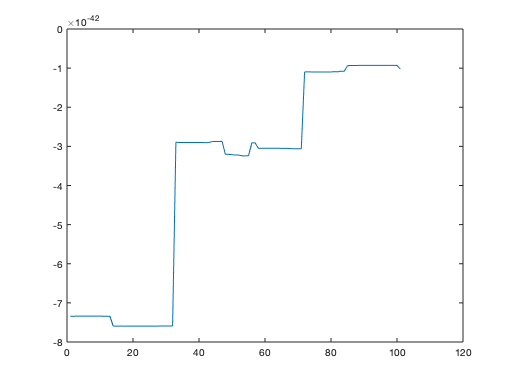


plot(U_hist); 

%%% Question 2 %%%
rho_2 = 0.1:0.1:1;
T_2 = [2,0.9];
for i = 1:length(T_2)
   T = T_2(i)
    P_rho = [];
    for j = 1:length(rho_2)
        rho = rho_2(j)
        [pos_hist, P_hist, vir_hist, U_hist] = MC_Project_Pipeline(N, R, L, sigma, epsilon, iterations, rho);
        P_avg = mean(P_hist); 
        P_rho{i} = [P_rho, P_avg];
        %run monte carlo code, extract P(rho) and store in a matrix  
        j = j+1
    end
    %store matrix from inner for loop as variable for that temperature
    %(should end up with two)
    subplot(1, 2, i); 
    plot(rho_2, P_rho); 
    i = i+1
end

T = 2

rho = 0.1000

    "run number is "    "10"

    "run number is "    "20"

    "run number is "    "30"



% plot P(rho) for T_2[1]
% plot P(rho) for T_2[2]
%answer: for which densities and temperatures you observe phase separation?

%%% Question 3 %%%
% snapshots showing phase separation, liquid, gas (x3)

%%% Question 4 %%%
% up to what density is ideal gas good approx.?
Kb = 1.38064852 * 10^-23; 
T = 0.9; %redefine boltzmann constant and T so this section can run on it's own
pressure = [0.0802, 0.1034, 0.1534, 00.1496, 0.1398, 0.4560, 1.7994]; %pressure (y axis) data
rho = 0.1:0.1:0.7; %density (x axis) data
epsilon1=1

epsilon1 = 1

% boltz = exp(-Uavg/(Kb*T))%Beta should be in reduced units so B=1/K
% Attempt to answer 
boltz=1/(T*epsilon1)

boltz = 1.1111

Pigl=rho./boltz

Pigl =     0.0900    0.1800    0.2700    0.3600    0.4500    0.5400    0.6300


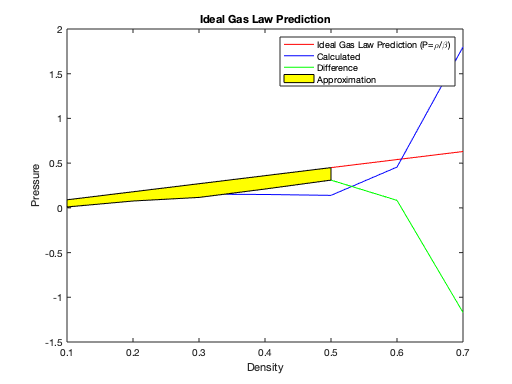

x= rho(1:5);
y1= Pigl(1:5);
y2= pressure(1:5);
Difference = -pressure + Pigl;
y3= Difference(1:5);
plot(rho,Pigl,'r')
hold on
plot(rho,pressure,'b')
plot(rho,Difference,'g')
x2 = [x, fliplr(x)];
inBetween = [y1, fliplr(y3)];
fill(x2, inBetween, 'y');
title('Ideal Gas Law Prediction')
xlabel('Density')
ylabel('Pressure')
legend('Ideal Gas Law Prediction (P=\rho/\beta)','Calculated','Difference','Approximation')

%%% Question 5 %%%
% gaussian displacement instead of uniform

%%% Question 6 %%%
% displace all particles every move, max displacement where 50% accepted